# BPSK Modulator Simulation

## Theoretical background

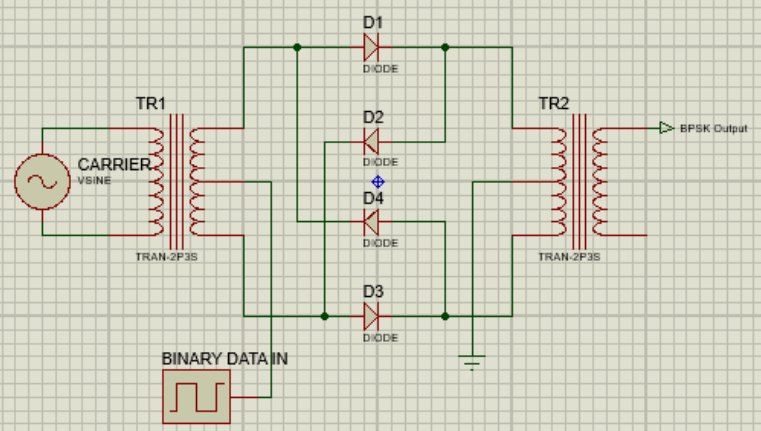

- Above is a BPSK modulator which uses a balanced modulator. 

- The carrier wave is a high frequency sinusoidal wave and the binary data input waveform is a square wave of amplitudes +1 V and -1 V corresponding to binary values 1 and 0 respectively. 

- The diodes control the "orientation" of the sine wave that is passed through the transformer TR2. When the binary data input is +1 V, the BPSK output is equal to the carrier wave, or has no phase difference. When the binary data input is - 1 V, the BPSK output and the carrier wave will have a 180-degree phase difference, hence the modulation scheme "BPSK".

- The simulation will assume the transformers TR1 and TR2 specifications to be 1:1 and that there is no voltage drop across the diodes. Hence only the phase of the waveforms shall change.

- Below are the expected waveforms (from [What is Phase Shift Keying (PSK)? BPSK modulation, BPSK demodulation, advantages, disadvantages and applications of PSK - Electronics Coach](https://electronicscoach.com/phase-shift-keying.html)):

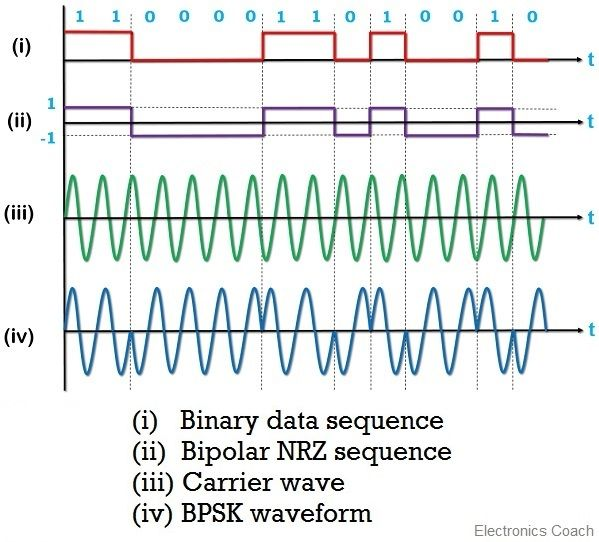

## BPSK modulator (No graphing of the waveforms)

- Scheme for generating the complex envelope is updated to match that of the built in function.

- Simulation without graphing the waveforms can accommodate more input bits since plotting requires 10k times more samples.

### Model the binary data

nbits = 1e6;
bits = randi([0 1], 1, nbits)

### Generate the complex envelope

cmplx_env = zeros(size(bits));
for i = 1 : length(bits)
    switch(bits(i))
        case 1
            cmplx_env(i) = -1;
        case 0
            cmplx_env(i) = 1;
        otherwise
            error("Error in bit generation")
    end
end
cmplx_env = complex(cmplx_env)

### Add white Gaussian noise to the complex envelope

SNR = 10;
noise_cmplx_env = awgn(cmplx_env, SNR)

### Plot the BPSK constellation diagram

figure(1)
scatterplot(noise_cmplx_env)
title("BPSK Constellation Diagram")
grid on

### Recover the bits from the noisy BPSK-modulated signal

recovered_bits = zeros(size(bits));
for i = 1 : length(noise_cmplx_env)
    if real(noise_cmplx_env(i)) < 0
        recovered_bits(i) = 1;
    elseif real(noise_cmplx_env(i)) >= 0 
        % do nothing since array is already zeros
    else
        error("Error in complex envelope generation")
    end
end

### Compute for the bit error rate

[number, ratio] = biterr(bits, recovered_bits);
fprintf("For SNR of " + num2str(SNR) + ", the BPSK modulation system produced " + num2str(number) + ...
    " number of bits in error. Resulting BER is " + num2str(ratio*100) + " percent.")

## Replication of BPSK using built-in MATLAB functions

### Generate the complex envelope using the pskmod() function

complex_envelope = pskmod(bits, 2)

### Add white Gaussian noise to the modulated waveform

noise_complex_envelope = awgn(complex_envelope, SNR)

### Recover the bits 

recovered_bits = pskdemod(noise_cmplx_env, 2)

### Plot the BPSK constellation diagram

clf
figure(2)
scatterplot(noise_cmplx_env)
title("BPSK Constellation Diagram")
grid on

### Compute for the bit error rate

[number, ratio] = biterr(bits, recovered_bits);
fprintf("For SNR of " + num2str(SNR) + ", the BPSK modulation system produced " + num2str(number) + ...
    " number of bits in error. Resulting BER is " + num2str(ratio*100) + " percent.")

## Simulation of BPSK modulator

### Model the carrier

fc = 1e6;
Ac = 1;

### Generate the time vector

t = linspace(0, 1/fc, fc);

### Model the binary data

% nbits = 8;
% bits = randi([0 1], 1, nbits)
bits = [1 0 1 0 1 0 0 1]

### Generate the binary waveforms

bin = zeros(size(bits));
binwave = [];
NRZ = [];
for i = 1 : length(bin)
    if bits(i) == 1
        bin(i) = 1;
        NRZ = [NRZ ones(1, fc)];
        binwave = [binwave ones(1, fc)];
    elseif bits(i) == 0
        bin(i) = -1;
        NRZ = [NRZ -ones(1, fc)];
        binwave = [binwave zeros(1, fc)];
    end
end

### Generate the carrier waveform

T = linspace(0, length(bin)/fc, length(bin)*fc);
carrier = Ac.*sin(2*pi*fc*T);

### Generate the complex envelope

cmplx_env = complex(bin);

### Add white Gaussian noise to the complex envelope

SNR = 10;
noise_cmplx_env = awgn(cmplx_env, SNR);

### Generate the BPSK-modulated waveform

BPSK = [];
for i = 1 : length(bin)
    if real(noise_cmplx_env(i)) >= 0
        BPSK = [BPSK carrier(1 : fc)];
    elseif real(noise_cmplx_env(i)) < 0
        BPSK = [BPSK -carrier(1 : fc)];
    end
end

### Display all generated waveforms

clf
figure(3)
tiledlayout(2, 2)
sgtitle("BPSK Modulator")

nexttile % Binary data sequence
plot(T, binwave, LineWidth=2)
title("Binary data sequence")
xlabel("Time (sec)")
ylabel("Voltage (V)")
xlim([0 max(T)])
ylim([-2 2])
for i = 0 : length(bin), xline(i/fc, LineStyle='--', Color='red'); end
grid on

nexttile % Bipolar NRZ sequence
plot(T, NRZ, LineWidth=2)
title("Bipolar NRZ sequence")
xlabel("Time (sec)")
ylabel("Voltage (V)")
xlim([0 max(T)])
ylim([-2 2])
for i = 0 : length(bin), xline(i/fc, LineStyle='--', Color='red'); end
grid on

nexttile % Carrier wave
plot(T, carrier, LineWidth=2)
title("Carrier wave")
xlabel("Time (sec)")
ylabel("Voltage (V)")
xlim([0 max(T)])
grid on

nexttile % BPSK-modulated waveform
plot(T, BPSK, LineWidth=2)
title("BPSK-modulated waveform")
xlabel("Time (sec)")
ylabel("Voltage (V)")
xlim([0 max(T)])
for i = 0 : length(bin), xline(i/fc, LineStyle='--', Color='red'); end
grid on